clearvars; close all; clc;
set(0,"DefaultAxesFontSize",8)

# Class: lspsys

JVsound, J.G. Vermond

disp(datetime("today"))

   06-Sep-2026



## Description

lspsys represents a loudspeaker system, including its environment.

## Examples

% Initiation of an object:
lspsys1		= lspsys;

% Enclosure:
e			= comp.closedbox;
e.Vr		= 200e-3;

% Driver:
d			= load("bc21sw152_8.mat").bc21sw152_8;

% Assign the enclosure to the loudspeaker system and the driver to the
% enclosure:
lspsys1.enclosure			= e;
lspsys1.enclosure.driver	= d;

% We request the result object:
res							= lspsys1.result;

We plot the electric impedance of system

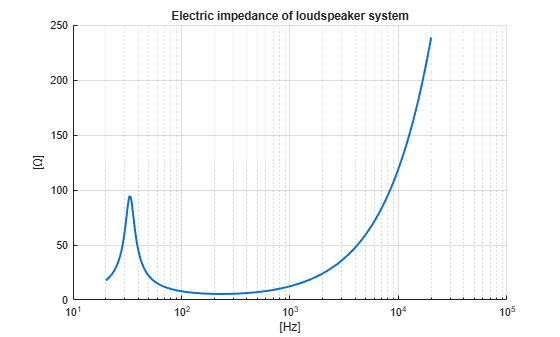

fig1				= figure;
ax1					= axes; hold on; grid on;
ax1.XScale			= "log";
ax1.Title.String	= "Electric impedance of loudspeaker system";
ax1.XLabel.String	= "[Hz]";
ax1.YLabel.String	= "[\Omega]";

plot(ax1,res.f,abs(res.ze),LineWidth=1.5)

Wave number, spatial angular frequency in rad/m


$$k = \frac{\omega}{c} = \frac{2\pi f}{c} = \frac{2\pi}{\lambda}$$
